% This script demonstrates linear model predictive control for the
% double integrator benchmark

% load system parameter
ParamTerm = param_doubleIntegrator();

Param = ParamTerm;
Param.xf = zeros(2,1);
Param.x0 = [3;-3];

% compute terminal region
OptsTerm.Tdomain = interval(-ones(2,1),ones(2,1));
OptsTerm.timeStep = 0.1;
OptsTerm.N = 30;
OptsTerm.Q = eye(2);
OptsTerm.R = eye(1);
OptsTerm.genMethod = 'sampling2D';
OptsTerm.costFun = 'sum';

T = computeTerminalRegion('doubleIntegrator','zonoLinSys', ...
                                                    ParamTerm,OptsTerm);

Computing safe terminal set (phase 1) ...
Computing safe inital set (phase 2) ...
Succesfully computed the terminal region.



% controller settings
Opts.termReg = T;           % terminal region 
Opts.tOpt = 8;              % prediction horizon
Opts.N = 40;                % number of time steps
Opts.realTime = true;       % require that computations run in real time

% model predictive control
res = linSysMPC('doubleIntegrator',Param,Opts);

Switch to new solution
Switch to new solution
Switch to new solution
Switch to new solution
Switch to new solution
Switch to new solution
Switch to new solution
Switch to new solution
Switch to new solution
Switch to new solution
Switch to new solution
Switch to new solution
Switch to new solution
Switch to new solution
Switch to new solution
Switch to new solution
Switch to new solution
Switch to new solution
Switch to new solution
Switch to new solution
Switch to new solution
Switch to new solution
Switch to new solution
Switch to new solution


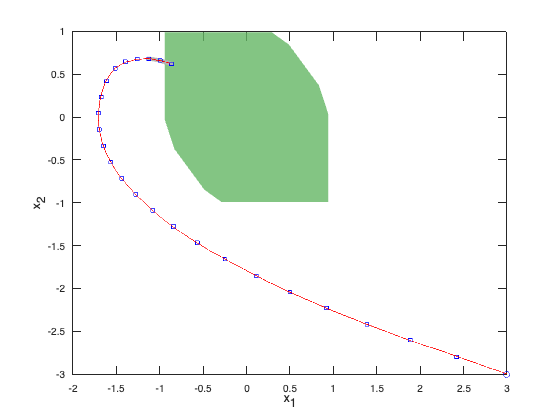


% visualization
figure; hold on; box on
plot(Opts.termReg.set,[1,2],'FaceColor',[100 182 100]./255,...
     'EdgeColor','none','FaceAlpha',0.8);
plotReach(res,[1,2],[.7 .7 .7]);
plotReachTimePoint(res,[1,2],'b');
plotSimulation(res,[1,2],'r');
xlabel('x_1'); ylabel('x_2');